## Topic 4 Systems of first-order ODE equations

This liveScript accompanies class materials for Topic 3B. These exercises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

### Numerical integration of a coupled first-order ODE system:

**Exercise 1****: **Use the MATLABfunction file “My_ODE_Function.m” to explore the above 2-d ODE. What happens as you change a, b, d and d as follows:

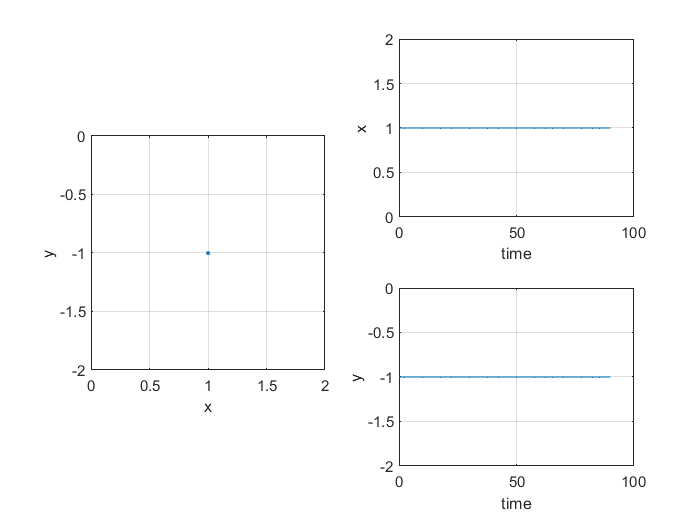

[t x] = Int_My_ODE_Function([1 -1],90);

**Exercise 1b****:** modify the “My_ODE_Function.m” function to allow speficication of model parameters as inputs.

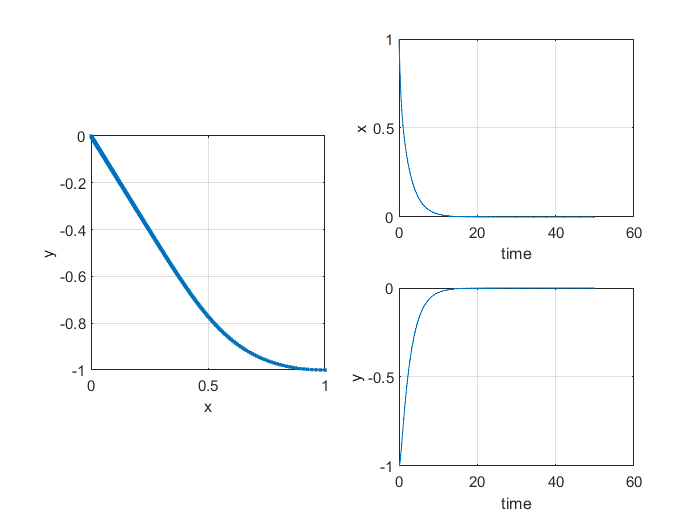

 [t x] = Int_My_ODE_Function_param([1 -1],50,-2,-1,-1,-1);

### Lotka-Volterra model

Rabbit population - logistic curve growth with limitation on max population. The number of rabbits increases exponentially *(aX)* until their population rises to its limit due to limitations in food resources *(–mX^2). *However, the full predator-prey model adds interaction between the two species via the multiplicative term *XY*, and this is its primary departure from the single-equation logistic model.

The justification for the multiplicative term is that XY represents the probability of one on one encounter for the prey (X) and the predator (Y). The parameter associated with XY captures how successful the predators are.

#### Visualize logic of the prey part of the Lotka-Volterra model:

syms f(x) a m

f(x) = a*x-m*x^2

$$f(x) = a\,x-m\,x^{2}$$


% Find fixed points
fp = solve(f(x)==0)

$$fp = \left(\begin{array}{c} 0\\ \frac{a}{m} \end{array}\right)$$


% Determine fixed point stability
f_d(x) = diff(f(x));
f_d(fp)

$$ans = \left(\begin{array}{c} a\\ -a \end{array}\right)$$


a_in = 1.5

a_in = 1.5000

m_in = 1

m_in = 1


figure
fplot(subs(f(x),{a,m},{a_in,m_in}))
hold

Current plot held


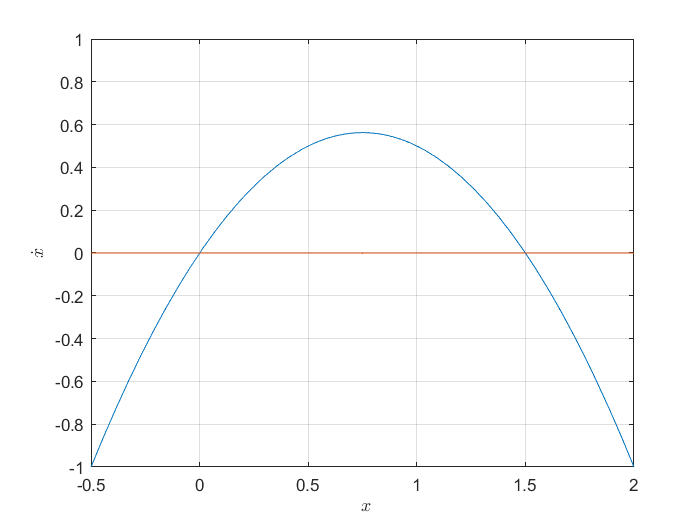

fplot(0)
grid on
ylim([-1 1])
xlim([-0.5 a_in/m_in+0.5])
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')

### Lotka-Volterra without crowding/resource term - practice with numerical integration of systems of ODEs

The predator-prey model is often introduced without the crowding and resource limitation terms *(mX2* and *nY2)* found in Equations 3.1 and 3.2 to show how the population interactions work by themselves.

**Exercise 2****: **Use the MATLABfunction file “Lotka_Volterra.m” to explore the themodel without resource limitation (i.e, set m and n = 0 for all simulations. What happens as you change a, b, d and d as follows:

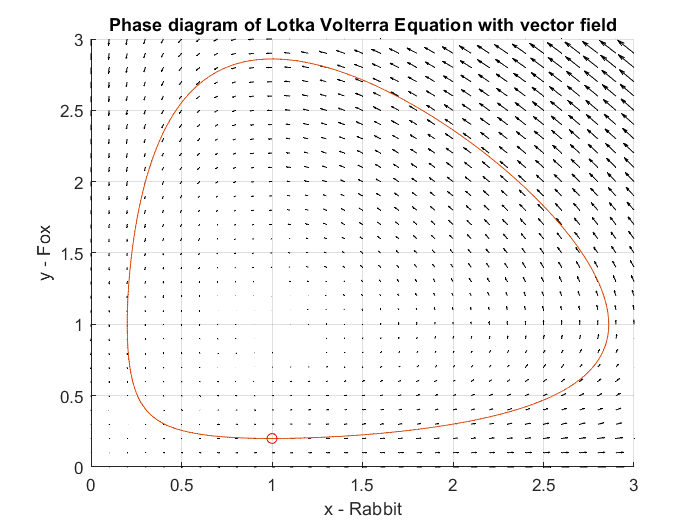

processing... ... ...


figure
[t x] = Lotka_Volterra([1],[.2] ,1,1,0, 1,1,0, 20);


figure
plot(t,x(:,1),'.-')
hold

Current plot held


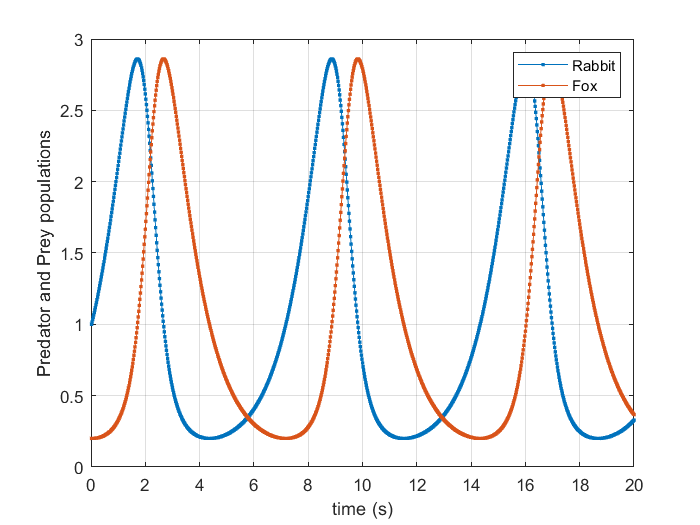

plot(t,x(:,2),'.-')
legend('Rabbit','Fox')
grid on
xlabel('time (s)')
ylabel('Predator and Prey populations')

**Exercise 3****: **What happens as you change the initial conditions as follows: Plot the x-y figure of the systems’ trajectory on the same plot.

figure
[t x] = Lotka_Volterra([1],[.2] ,1,1,0, 1,1,0, 20);

processing... ... ...


hold

Current plot held


[t x] = Lotka_Volterra([1],[.5] ,1,1,0, 1,1,0, 20);

processing... ... ...


[t x] = Lotka_Volterra([1],[.9] ,1,1,0, 1,1,0, 20);

processing... ... ...


[t x] = Lotka_Volterra([2],[.9] ,1,1,0, 1,1,0, 20);

processing... ... ...


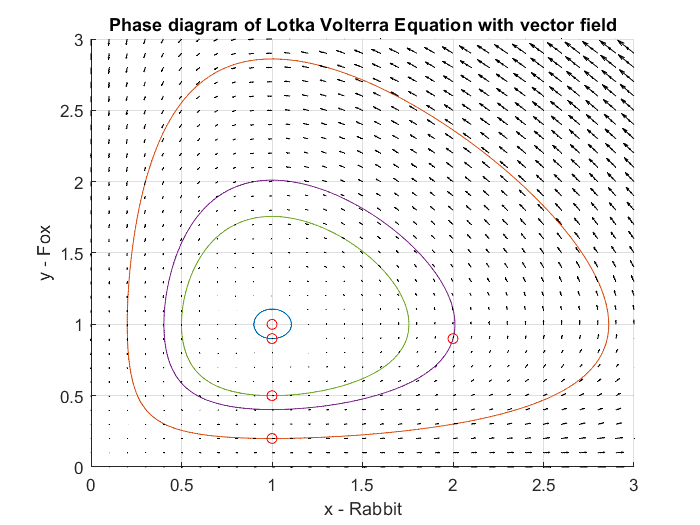

processing... ... ...


[t x] = Lotka_Volterra([1],[1] ,1,1,0, 1,1,0, 20);

**Exercise 4****: **What happens as you change the c parameter while keeping the initial conditions the same? Plot the x-y figure of the systems’ trajectory on the same plot.

figure
[t x] = Lotka_Volterra([1],[.5] ,1,1,0, 1,1,0, 20);

processing... ... ...


hold

Current plot held


[t x] = Lotka_Volterra([1],[.5] ,1,1,0, 2,1,0, 20);

processing... ... ...


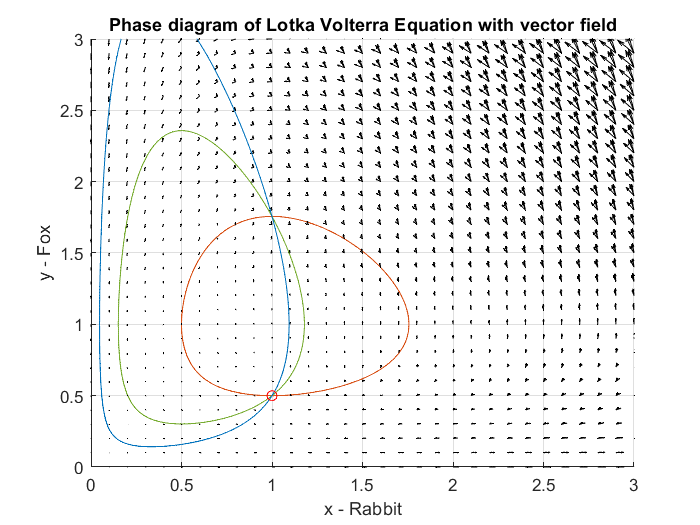

processing... ... ...


[t x] = Lotka_Volterra([1],[.5] ,1,1,0, 3,1,0, 20);

### Constructing vector fields - Lotka Volterra model

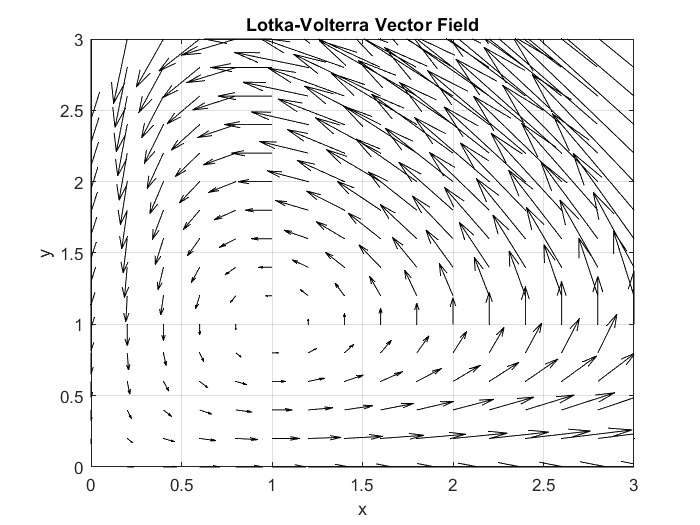

% Create grid of x and y values where the ODEs will be evaluated
[x,y] = meshgrid(0:.2:3,0:.2:3);

% Find the values of dx/dt and dy/dt at all the x,y grid values
a = 1;
b = 1;
m = 0;

c = 1;
e = 1;
n = 0;

u = a.*x - b.*x.*y - m.*x.^2;
v = c.*x.*y-e.*y-n.*y.^2;

% plot the vectors with origin and x,y and slope given by dx/dt and dy/dt
figure
quiver(x,y,u,v,1,'k')
grid on
xlabel('x')
ylabel('y')
title('Lotka-Volterra Vector Field')

xlim([min(min(x)), max(max(x))])
ylim([min(min(y)), max(max(y))])

**Exercise 5. **Plot the vector field for following system with the parameter a = -1, -0.5, 0, 0.5 and 1:

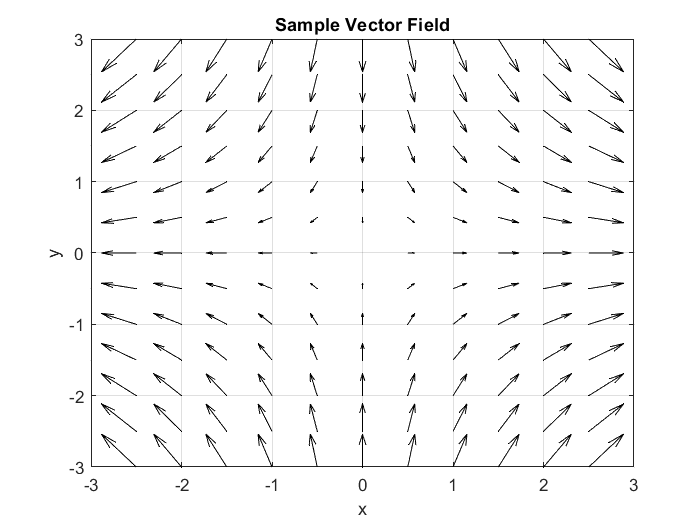

% Create grid of x and y values where the ODEs will be evaluated
[x,y] = meshgrid(-3:.5:3,-3:.5:3);

% Find the values of dx/dt and dy/dt at all the x,y grid values
a = 1;

u = a.*x;
v = -y;

% plot the vectors with origin and x,y and slope given by dx/dt and dy/dt
figure
quiver(x,y,u,v,1,'k')
grid on
xlabel('x')
ylabel('y')
title('Sample Vector Field')

xlim([min(min(x)), max(max(x))])
ylim([min(min(y)), max(max(y))])

**Lotka-Volterra model with resorse limitations.**

Now let's add the resource limitation terms *(mX2* and *nY2) to the Lotka-Volterra model and examine how it changes the vector field and the phase diagrams.*

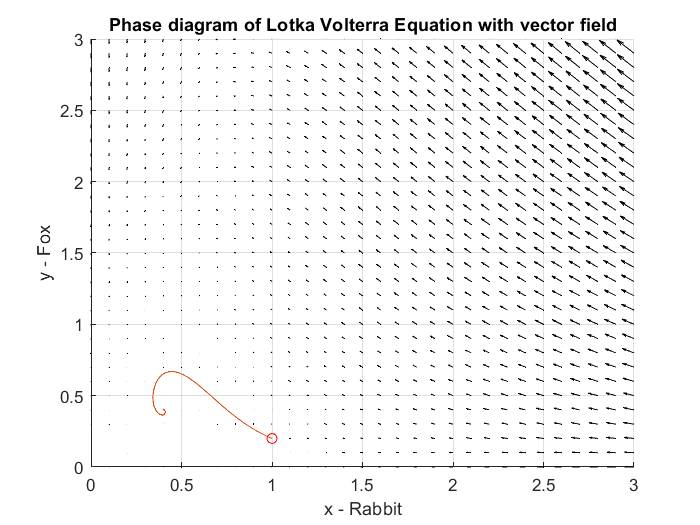

processing... ... ...


figure
[t x] = Lotka_Volterra([1],[.2], 1,1,1.5, 3,1,0.5, 70);


figure
plot(t,x(:,1),'.-')
hold

Current plot held


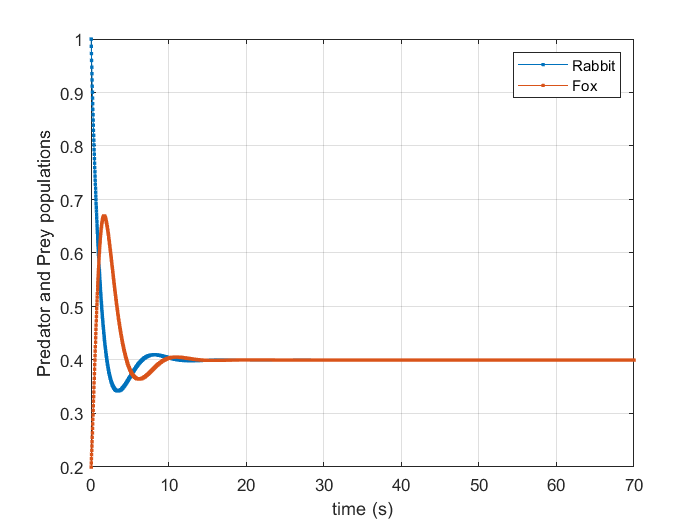

plot(t,x(:,2),'.-')
legend('Rabbit','Fox')
grid on
xlabel('time (s)')
ylabel('Predator and Prey populations')

**Exercise 6. **Plot the Lotka-Volterra model with resourse limitations for the following initial conditions:

figure
[t x] = Lotka_Volterra([1],[.2], 1,1,1.5, 3,1,0.5, 20);

processing... ... ...


hold

Current plot held


[t x] = Lotka_Volterra([1],[.8], 1,1,1.5, 3,1,0.5, 70);

processing... ... ...


[t x] = Lotka_Volterra([.1],[.1], 1,1,1.5, 3,1,0.5, 70);

processing... ... ...


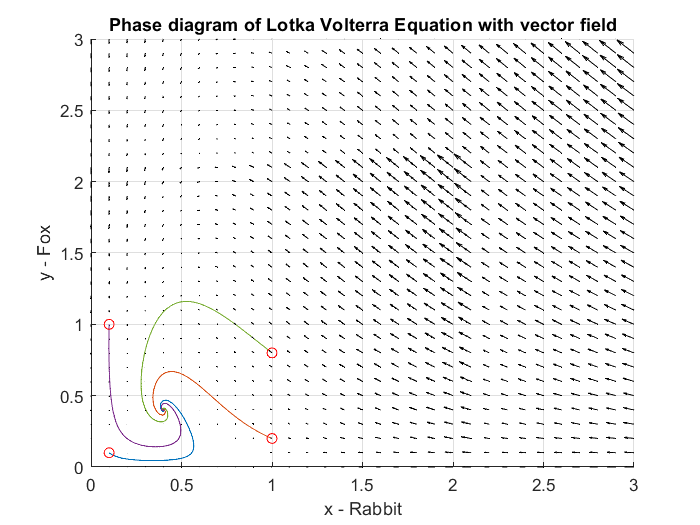

processing... ... ...


[t x] = Lotka_Volterra([.1],[1], 1,1,1.5, 3,1,0.5, 70);

### Finding fixed points

Find equilibrium points for the Lotka-Volterra model without the resource limitation

syms f(x) f(y) a b c e

f(x) = a*x-b*x*y

$$f(x) = a\,x-b\,x\,y$$

g(y) = c*x*y-e*y

$$g(y) = c\,x\,y-e\,y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = \left(\begin{array}{c} 0\\ \frac{e}{c} \end{array}\right)$$

$$sy = \left(\begin{array}{c} 0\\ \frac{a}{b} \end{array}\right)$$


a_in = 1;
b_in = 1;
c_in = 1;
e_in = 1;

figure
[t x] = Lotka_Volterra_v2([1],[.2] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


hold

Current plot held



% plot equilibrium point
plot(e_in/c_in,a_in/b_in,'*')

% plot trajectories for various initial conditions
[t x] = Lotka_Volterra_v2([1],[.3] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.4] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.4] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.7] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


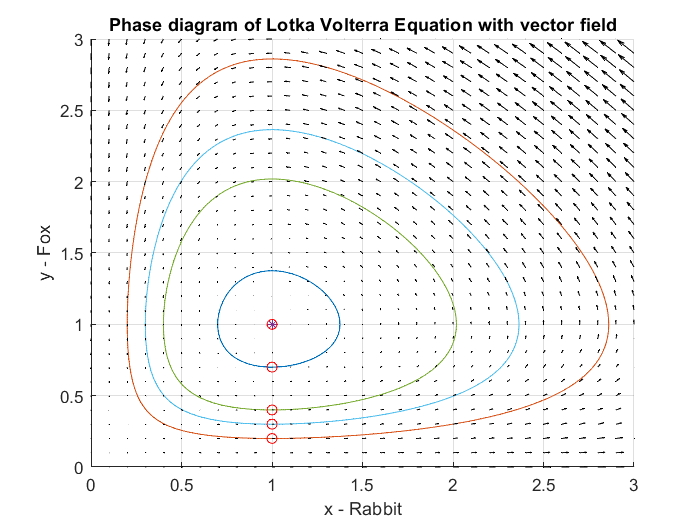

processing... ... ...



% initital condition at the equilibrium point
[t x] = Lotka_Volterra_v2([e_in/c_in],[a_in/b_in] ,a_in,b_in,0, c_in,e_in,0, 20);

Equilibrium points for the model with the resource limitation

syms f(x) g(y) a b c e m n 

f(x) = a*x-b*x*y-m*x^2

$$f(x) = a\,x-m\,x^{2}-b\,x\,y$$

g(y) = c*x*y-e*y-n*y^2

$$g(y) = c\,x\,y-n\,y^{2}-e\,y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = \left(\begin{array}{c} 0\\ \frac{b\,e+a\,n}{b\,c+m\,n}\\ \frac{a}{m}\\ 0 \end{array}\right)$$

$$sy = \left(\begin{array}{c} 0\\ \frac{a\,c-e\,m}{b\,c+m\,n}\\ 0\\ -\frac{e}{n} \end{array}\right)$$


a_in = 1;
b_in = 1;
c_in = 3;
e_in = 1;
m_in = 1.5;
n_in = 0.5;

figure
[t x] = Lotka_Volterra_v2([1],[.2] ,a_in,b_in,m_in, c_in,e_in,n_in, 70);

processing... ... ...


hold

Current plot held


% plot equilibrium point
plot((b_in*e_in + a_in*n_in)/(b_in*c_in + m_in*n_in),(a_in*c_in - e_in*m_in)/(b_in*c_in + m_in*n_in),'*')

% Let's try different initial conditions:
[t x] = Lotka_Volterra_v2([1],[.3] ,a_in,b_in,m_in, c_in,e_in,n_in, 70);

processing... ... ...


[t x] = Lotka_Volterra_v2([.1],[.1] ,a_in,b_in,m_in, c_in,e_in,n_in, 70);

processing... ... ...


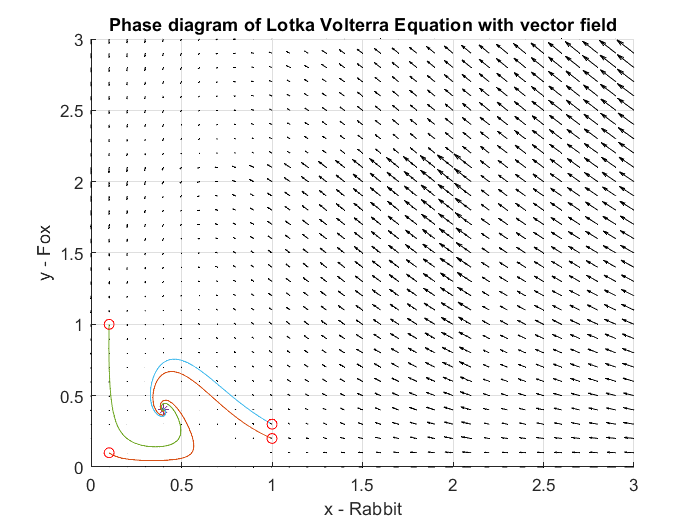

processing... ... ...


[t x] = Lotka_Volterra_v2([.1],[1] ,a_in,b_in,m_in, c_in,e_in,n_in, 70);

***Exercise ******7******. ***Use the ‘solve’ function in Matlab to find the fixed points for the following systems. Try doing it with and without specific parameter settings.

syms f(x) g(y) a

f(x) = a*x

$$f(x) = a\,x$$

g(y) = -y

$$g(y) = -y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = 0$$

$$sy = 0$$


% second equation
syms f(x) g(y) a b c d

f(x) = a*x + b*y

$$f(x) = a\,x+b\,y$$

g(y) = c*x + d*y

$$g(y) = c\,x+d\,y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = 0$$

$$sy = 0$$


%  Third equation
syms f(x) g(y) a b c e

f(x) = a*x - b*x*y

$$f(x) = a\,x-b\,x\,y$$

g(y) = c*x*y - e*y

$$g(y) = c\,x\,y-e\,y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = \left(\begin{array}{c} 0\\ \frac{e}{c} \end{array}\right)$$

$$sy = \left(\begin{array}{c} 0\\ \frac{a}{b} \end{array}\right)$$

### Isoclines

syms f(x) f(y) a b c e

f(x) = a*x-b*x*y

$$f(x) = a\,x-b\,x\,y$$

g(y) = c*x*y-e*y

$$g(y) = c\,x\,y-e\,y$$


[sx,sy] = solve(f(x)==0,g(y)==0)

$$sx = \left(\begin{array}{c} 0\\ \frac{e}{c} \end{array}\right)$$

$$sy = \left(\begin{array}{c} 0\\ \frac{a}{b} \end{array}\right)$$


a_in = 1;
b_in = 1;
c_in = 3;
e_in = 1;

figure
[t x] = Lotka_Volterra_v2([1],[.2] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


hold

Current plot held



% plot x-isoclines
xline(0,'r','linewidth',2)
yline(a_in/b_in,'r','linewidth',2)

% y-isoclines
yline(0,'b','linewidth',2)
xline(e_in/c_in,'b','linewidth',2)

% plot equilibrium point
plot(e_in/c_in,a_in/b_in,'*')

% plot trajectories for various initial conditions
[t x] = Lotka_Volterra_v2([1],[.3] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.4] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.4] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


[t x] = Lotka_Volterra_v2([1],[.7] ,a_in,b_in,0, c_in,e_in,0, 20);

processing... ... ...


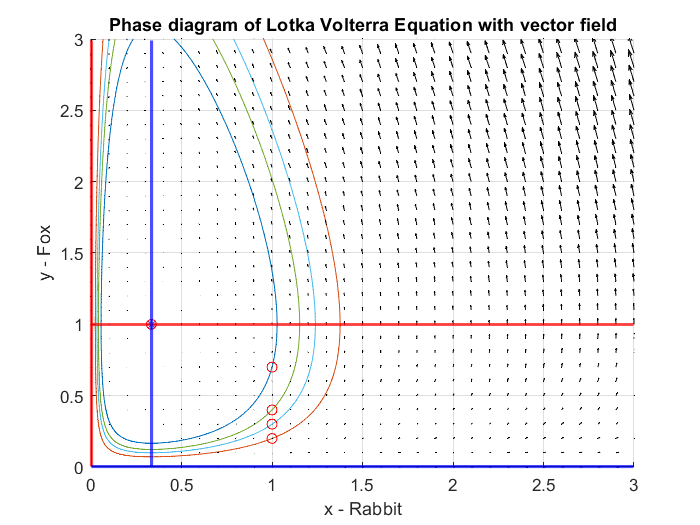

processing... ... ...



% initital condition at the equilibrium point
[t x] = Lotka_Volterra_v2([e_in/c_in],[a_in/b_in] ,a_in,b_in,0, c_in,e_in,0, 20);

### Define Equilibrium marsh

% Create grid of x and y values where the ODEs will be evaluated
[x,y] = meshgrid(0:.1:3,0:.1:3);

% Find the values of dx/dt and dy/dt at all the x,y grid values
a = 1;
b = 1;
m = 0;

c = 1.5;
e = 1;
n = 0;

u = a.*x - b.*x.*y - m.*x.^2;
v = c.*x.*y-e.*y-n.*y.^2;

% plot the vectors with origin and x,y and slope given by dx/dt and dy/dt
figure
quiver(x,y,u,v,1,'k')
grid on
xlabel('x')
ylabel('y')

xlim([min(min(x)), max(max(x))])
ylim([min(min(y)), max(max(y))])

% Plot equilibrium marsh
z = abs(v)<0.1 & abs(u)<0.1

z = 31×31 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

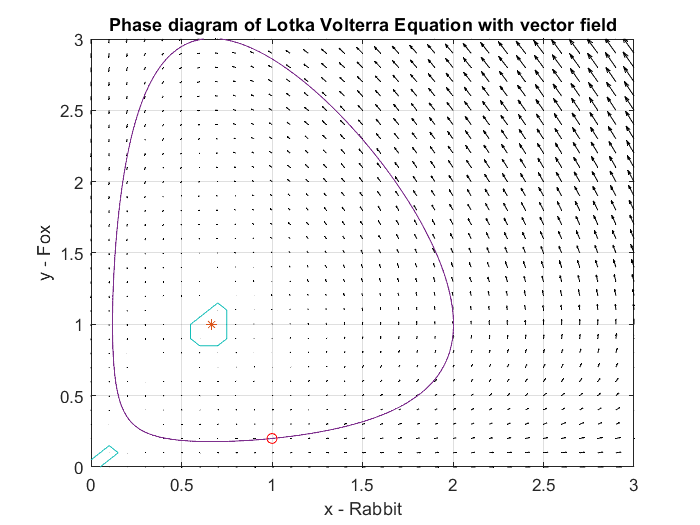

processing... ... ...


hold on
contour(x,y,z,1)

% plot equilibrium point
plot((b*e + a*n)/(b*c + m*n),(a*c - e*m)/(b*c + m*n),'*')
[t x] = Lotka_Volterra_v2([1],[.2] ,a,b,m, c,e,n, 70);